# Comparison between EMS

## Get current folder and add all folders to the path

currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
    (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
    ~isempty(currentfolder{end}))
    currentpath = fileparts(currentpath);
    currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath))

EMS_sim = [];
column_names = {};

## Get the data folder

folder_data = strcat(projectpath,'\Data\');

# Select the EMS to compare

## PI

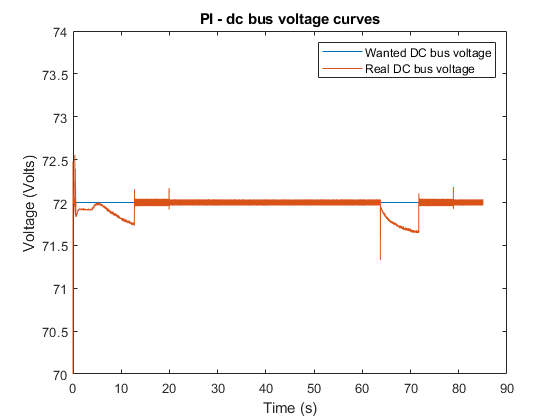

EMS_sim = [EMS_sim; PI];
column_names{end+1} = getVarName(PI);
bus_curve(PI,'PI');

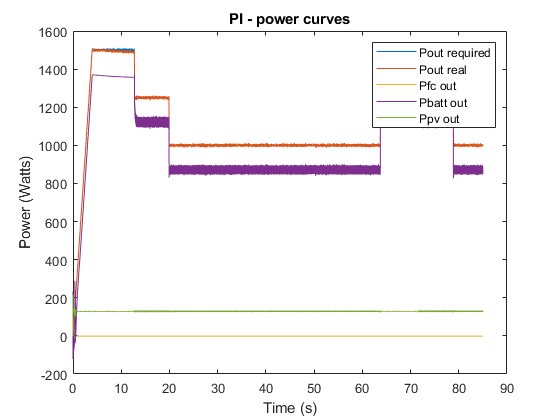

power_curve(PI,'PI');

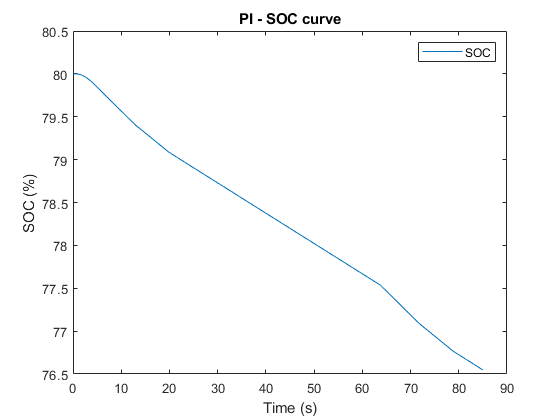

soc_curve(PI,'PI');

## SMC

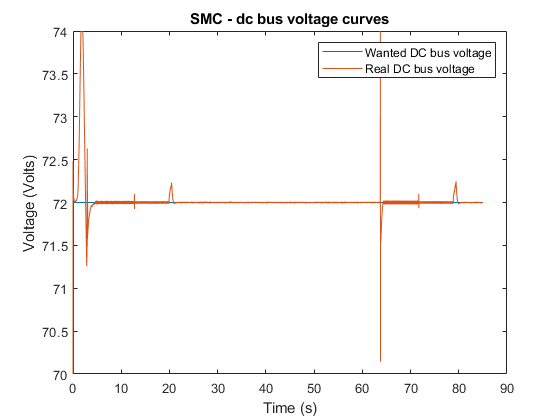

EMS_sim = [EMS_sim; SMC];
column_names{end+1} = getVarName(SMC);
bus_curve(SMC,'SMC');

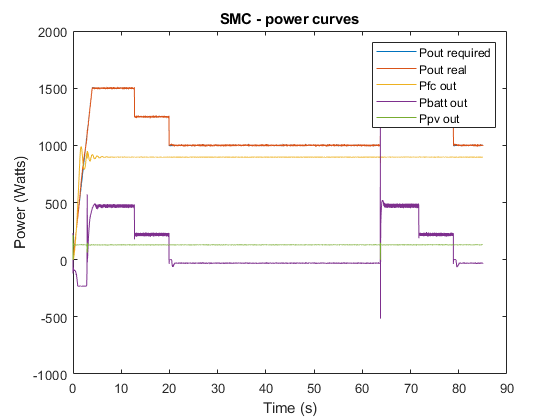

power_curve(SMC,'SMC');

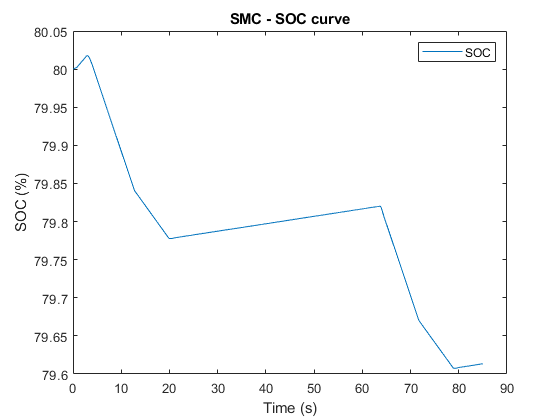

soc_curve(SMC,'SMC');

## FUZZY

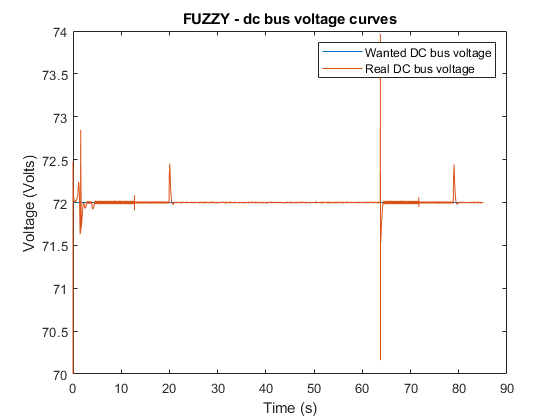

EMS_sim = [EMS_sim; FUZZY];
column_names{end+1} = getVarName(FUZZY);
bus_curve(FUZZY,'FUZZY');

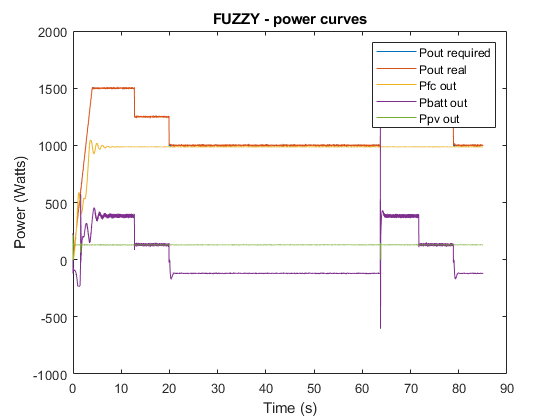

power_curve(FUZZY,'FUZZY');

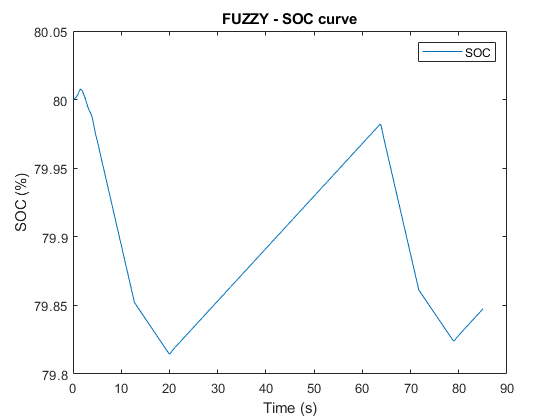

soc_curve(FUZZY,'FUZZY');

## ECMS

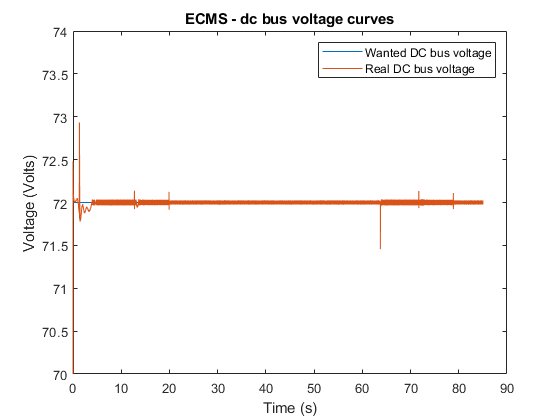

EMS_sim = [EMS_sim; ECMS];
column_names{end+1} = getVarName(ECMS);
bus_curve(ECMS,'ECMS');

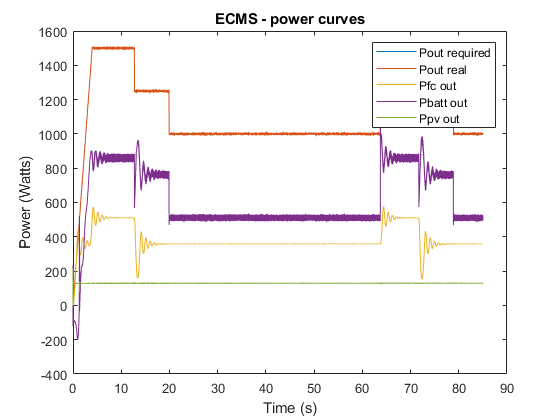

power_curve(ECMS,'ECMS');

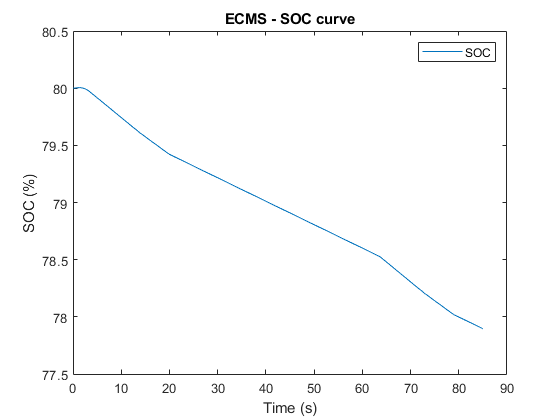

soc_curve(ECMS,'ECMS');

## EEMS

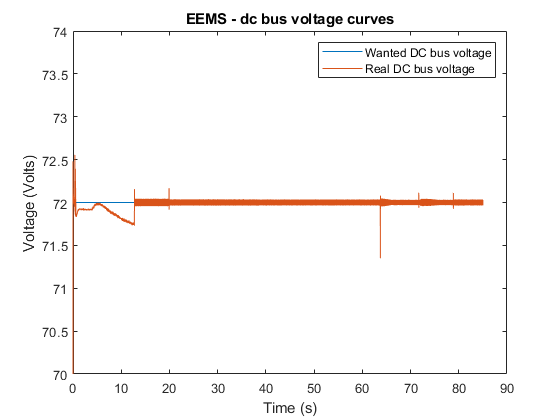

EMS_sim = [EMS_sim; EEMS];
column_names{end+1} = getVarName(EEMS);
bus_curve(EEMS,'EEMS');

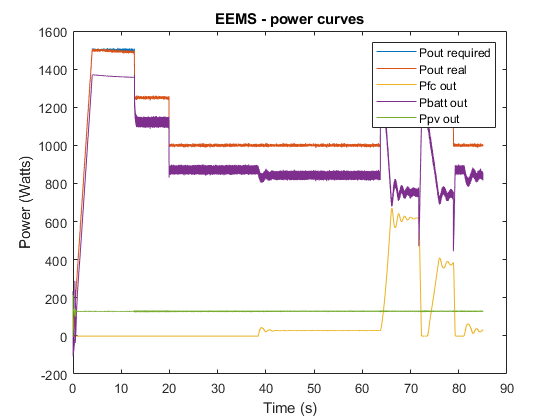

power_curve(EEMS,'EEMS');

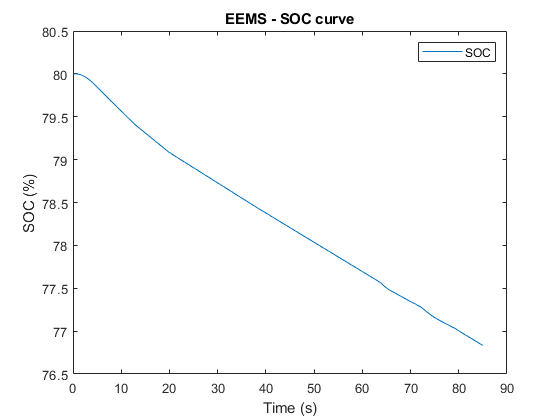

soc_curve(EEMS,'EEMS');

## D-ECMS

% EMS_sim = [EMS_sim; DECMS];
% column_names{end+1} = getVarName(DECMS);
% bus_curve(DECMS,'D-ECMS');
% power_curve(DECMS,'D-ECMS');
% soc_curve(DECMS,'D-ECMS');

## Get the stored data from data file

% tic
% PI = load(strcat(folder_data,'B80_PI_85.mat'));
% SMC = load(strcat(folder_data,'B80_SMC_85.mat'));
% FUZZY = load(strcat(folder_data,'B80_FUZZY_85.mat'));
% ECMS = load(strcat(folder_data,'B80_ECMS_85.mat'));
% toc

# Aligned Curves

## Voltage

% tic
% bus_curve(PI,'PI');
% bus_curve(SMC,'SMC');
% bus_curve(FUZZY,'FUZZY');
% bus_curve(ECMS,'ECMS');
% bus_curve(EEMS,'EEMS');
% bus_curve(DECMS,'DECMS');
% toc

## Power

% tic
% power_curve(PI,'PI');
% power_curve(SMC,'SMC');
% power_curve(FUZZY,'FUZZY');
% power_curve(ECMS,'ECMS');
% power_curve(EEMS,'EEMS');
% power_curve(DECMS,'DECMS');
% toc

## SOC

% tic
% soc_curve(PI,'PI');
% soc_curve(SMC,'SMC');
% soc_curve(FUZZY,'FUZZY');
% soc_curve(ECMS,'ECMS');
% soc_curve(EEMS,'EEMS');
% soc_curve(DECMS,'DECMS');
% toc

# Comparison data tables

## Power mean value

tic
m_power = mean_power(EMS_sim);
row_names = {'Pfc_in','Pfc_out','Pbatt_in','Pbatt_out','Ppv_in','Ppv_out','Psc'};
table_power = array2table(m_power','RowNames',row_names,'VariableNames',column_names)

table_power = 7×5 table
                     PI         SMC      FUZZY      ECMS      EEMS 
                 __________    ______    ______    ______    ______

    Pfc_in       8.7806e-05    989.26    1076.8    428.09    90.492
    Pfc_out         -1.0356     887.6    965.84       384    80.339
    Pbatt_in         1109.5    126.39    49.427    683.08    1020.1
    Pbatt_out        998.05    109.18    30.656    614.28     917.7
    Ppv_in           144.49    144.94    144.83    144.85     144.6
    Ppv_out          128.96    129.37    129.27    129.29    129.06
    Psc              1.3204    3.1694    3.1545     1.292    1.2147


toc

Elapsed time is 64.435893 seconds.


## Error mean value

tic
m_error = mean_error(EMS_sim);
row_names = {'RMSE P','RMSE V','MEP (%)','MEV (%)'};
table_error = array2table(m_error','RowNames',row_names,'VariableNames',column_names)

table_error = 4×5 table
                  PI         SMC        FUZZY        ECMS        EEMS  
               ________    ________    ________    ________    ________

    RMSE P       4.0561      4.3694      1.5588     0.70826       2.156
    RMSE V      0.10038     0.20856    0.050177    0.027522     0.05694
    MEP (%)     0.15376     0.10343    0.034205     0.04615    0.089563
    MEV (%)    0.076973    0.051336    0.017102    0.023079    0.044808


toc

Elapsed time is 7.355253 seconds.


## Consumption / SOC / SOH / age / sim time

tic
m_consu = consumption(EMS_sim);
row_names = {'H2 cons','SOC','SOH','age','sim time'};
table_consu = array2table(m_consu','RowNames',row_names,'VariableNames',column_names)

table_consu = 5×5 table
                    PI          SMC       FUZZY      ECMS       EEMS  
                __________    _______    _______    _______    _______

    H2 cons     6.3932e-08       1.34     1.5312    0.49019    0.10455
    SOC             76.547     79.613     79.848     77.896     76.833
    SOH            0.96547    0.99613    0.99848    0.97896    0.96833
    age                  1    0.99907    0.99933    0.99999          1
    sim time         94.67     46.547     68.694      335.8     98.714


toc

Elapsed time is 10.494158 seconds.
